# Analysis of microRNA data in relation to their therapeutic potential

## Background

## What is miRNA?

MicroRNA (**miRNA**) is a small non-coding RNA (~20-25 nucleotides) that regulates the expression of multiple target genes. As target recognition does not require full complementarity, a single miRNA can regulate multiple messenger RNAs (mRNAs). This combined effect by a single miRNA results in significant phenotypical changes that can be measured. 

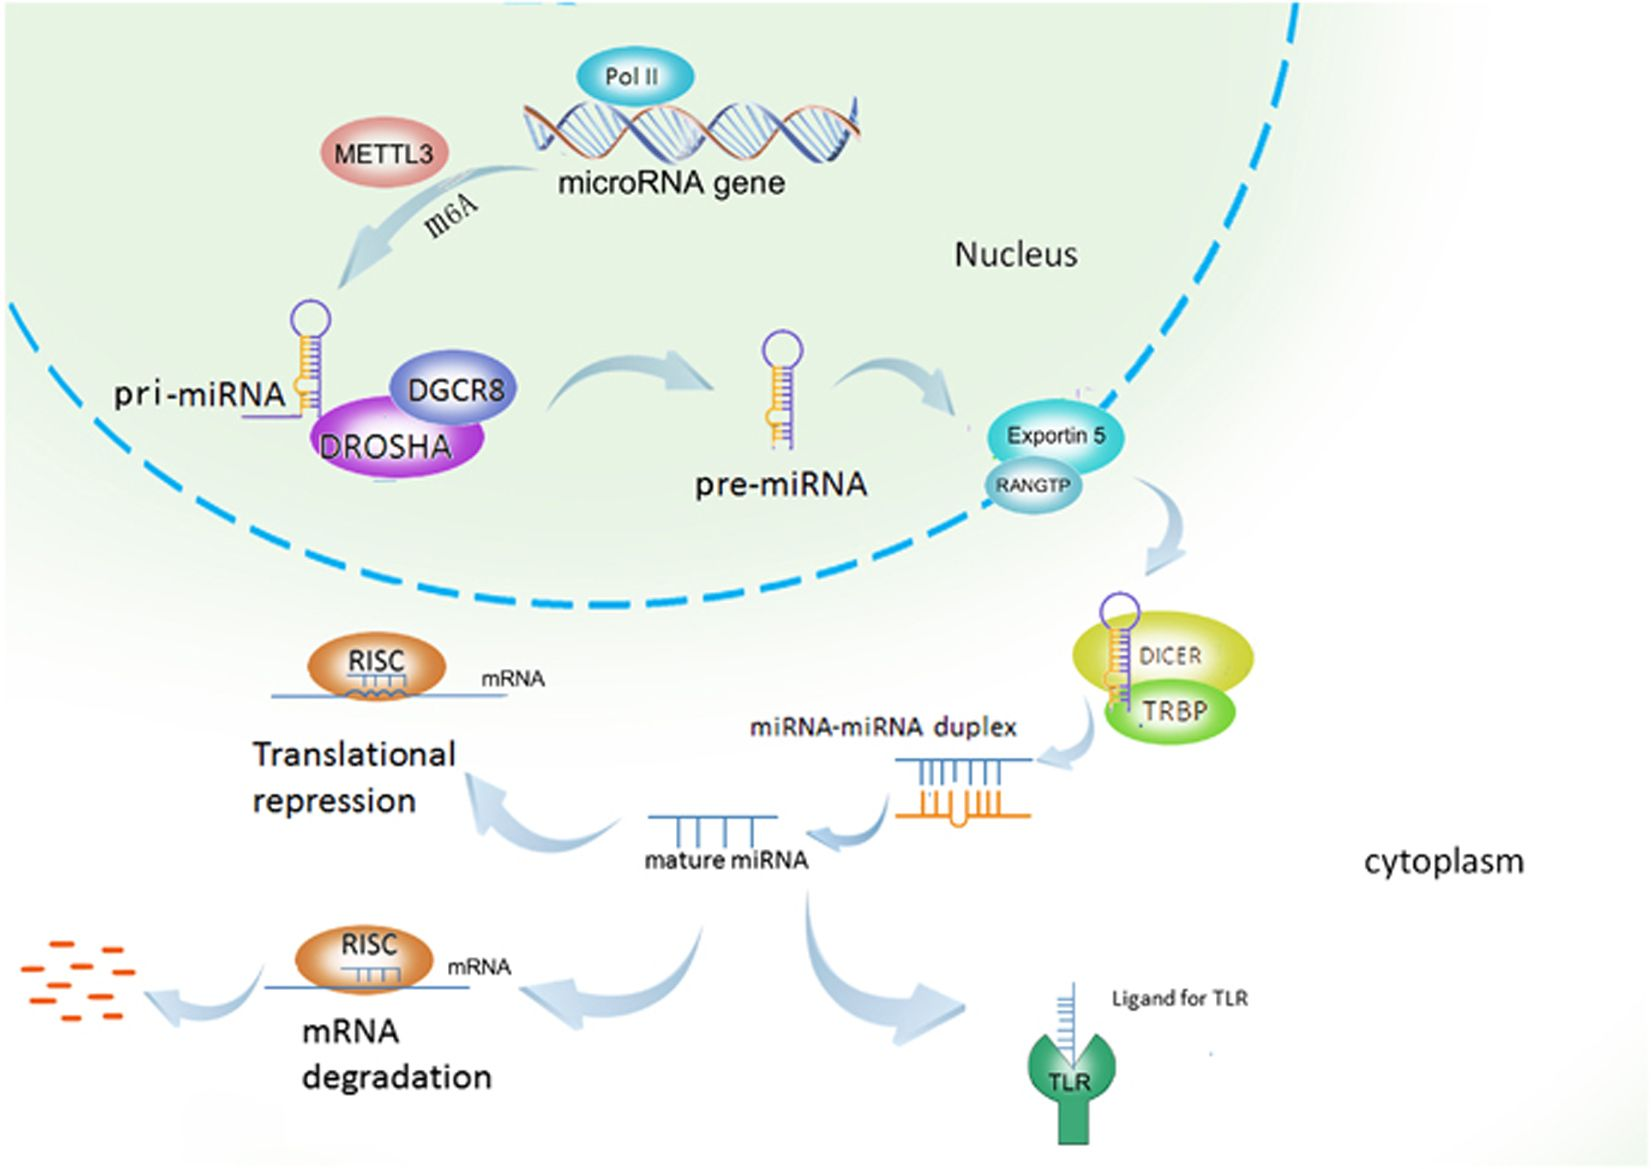

## miRNAs in Disease

Alteration in miRNA expression is associated with various diseases such as heart failure, cancer, and atherosclerosis to name a few. When a miRNA is differentially expressed in a specific disease, it can be considered as a "marker" for that disease. The table below provides a list of miRNAs that were found to be differentially expressed for various diseases: 

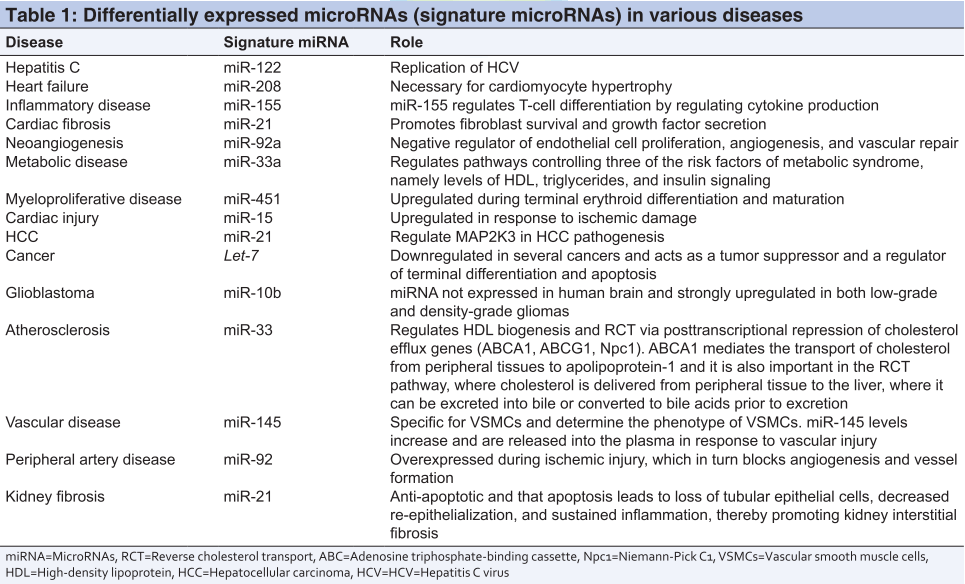

## miRNAs as Therapeutics

Due to their role in various diseases, miRNAs are being investigated as therapeutics. Similar to drug development, this process requires several steps: 

- Identify a "marker" miRNA for disease of interest (via miRNA profiling)

- Validation of "marker" miRNA (via loss/gain of function studies *in vitro* and *in vivo*)

- Pharmacological analysis (via delivery studies and pharmacokinetics/pharmacodynamics)

- Clinical trials (evaluation of drug efficacy and safety)

## Exploratory Analysis of miRNA Data

For today's lecture, we will be analyzing expression levels of 18 miRNAs collected from 70 lung tissue samples. This dataset includes samples from both healthy and diseased individuals, with the disease being lung cancer. Our main tasks for today will be to: 

- Determine the optimal number of clusters for this data using k-means clustering

- Visualize this data as a 2D scatter plot using principal component analysis

- Identify which miRNAs are differentially expressed between healthy and diseased individuals using hierarchical clustering

## Load and examine the data

To start, load the dataset (*miRNA_data.xlsx*) as a table and see what information is available. Based on the information provided, create a variable to store the patient IDs, a variable to store the health status for each patient, a variable to store the miRNA names, and a variable to store the miRNA expression data as a matrix:

% Load + view the dataset

% Create a variable for patient IDs

% Create a variable for patient health status

% Create a variable for miRNA names

% Create a variable for miRNA expression data


Plot a histogram (use the `hist` function) of the expression data for the first five miRNAs (make sure to include axis labels and a title): 

% Histogram of miRNA expression data


Questions: What do you notice about the expression level for these miRNAs? 

## Determine the optimal k value using k-means clustering

I will first show a short demo of what we will be doing for this section: 

% Demo for k-means clustering                                 
idx = kmeans({miRNA data array}, 2);     % identify clusters with k-means clustering
s = silhouette({miRNA data array}, idx); % determine silhouette values 
s_score = mean(s)                        % calculate silhouette score 

Now I want you to carry out these steps for k values ranging from 2 to 10 and store the silhouette scores you calculate. This will help us to quantitatively determine the best estimate for how many clusters the data separates into. Below is a base template to help you get started (you'll only need to modify the parts in curly brackets):

% Create a vector of k values ranging from 2 to 10
{vector of k values}

% For-loop to calculate the silhouette statistic for different k values
n = length({vector of k values});   % number of k values
s_list = zeros(n, 1);               % variable to store silhouette statistic values
for i = 1:n
    % Use the kmeans function to cluster patients into k clusters
    idx = kmeans({miRNA data array}, {k value});
    % Use the silhouette function to determine silhouette values
    s = silhouette({miRNA_data array}, idx);
    % Calculate the silhouette score by taking the mean
    s_list(i) = mean(s);
end
table({vector of k values}', s_list)

Question: What is the value for the max silhouette score? Which k value does this correspond with? 

Based on your answer to the question above, generate a silhouette plot:

% Silhouette plot based on best k value


Question: Are there any negative silhouette values? If so, what does this imply?

Using your variable for patient health status, assess how patients cluster based on your `idx` variable from k-means clustering: 

% Cluster patients by health status using idx variable from kmeans


Question: What do you notice from this assessment? 

## Visualize the data in lower dimension using PCA

Now we'll apply principal component analysis (PCA) to visualize our data within a lower-dimensional space. Use the `pca` function to determine the PC coefficint matrix (`P`), the transformed data matrix (`Y`), and a vector for the variance explained (`explained`). Then generate a scatter plot of the transformed data for PC1 vs. PC2, using patient health status for group labeling (Note: be sure to standardize the data before doing PCA):

% Do PCA (determine PC matrix, transformed data matrix, and variance explained)

% Visualize transformed data on PC1 vs. PC2 plot (label = patient health status)


Question: Based on the plot of PC1 vs. PC2, how many distinct clusters can you identify? How much variance do PC1 and PC2 account for?

Question: Do the PCA results match what we determined from k-means clustering?

Create a table of miRNA gene names matched with corresponding coefficients of the principal component that best separates the data: 

% Create table of genes matched to coefficients of best PC


Question: Which miRNA has the greatest weight for this PC?

## Identify differentially expressed miRNAs using hierarchical clustering

Create a clustergram of the expression data, using patient health status to label the rows and the miRNA gene names to label the columns. Also be sure to standardize all values by column:

% Create clustergram (label rows, label columns, and standardize by
% columns)


Question: Based on how the rows (patients) cluster, does this match our results from k-means clustering and PCA?

Generate the clustergram again, but this time use correlation as the distance metric for both rows and columns: 

% Generate clustergram (label rows, label columns, standardize by columns, 
% and use correlation as the distance metric for both rows and columns)


Question: How did the clustering change? Does this match our results from k-means clustering and PCA?

Question: Based on the patterns seen in the clustergram, which miRNAs are differentially expressed between healthy and diseased individuals? 

## Final Comments

The exploratory analysis that we did today shows how unsupervised learning methods can be applied to assess miRNA data. Though the dataset we used was small, we were able to assess how some miRNAs are differentially expressed between healthy and diseased individuals. When considering miRNAs for therapeutic potential, one would typically compare thousands of miRNA profiles and carry out statistically rigorous steps to identify marker miRNAs. For the purposes of this lesson, only exploratory and visual assessment of the miRNA data was covered.

## References

- [Peng & Croce (2016)](https://pubmed.ncbi.nlm.nih.gov/29263891/) - miRNA mechanism schematic

- [Christopher et al. (2016)](https://pubmed.ncbi.nlm.nih.gov/27141472/) - table of differentially expressed miRNAs in disease

- [Nana-Sinkan, Patrick & Croce (2011)](https://pubmed.ncbi.nlm.nih.gov/21420032/) - additional reading on miRNAs for cancer therapy